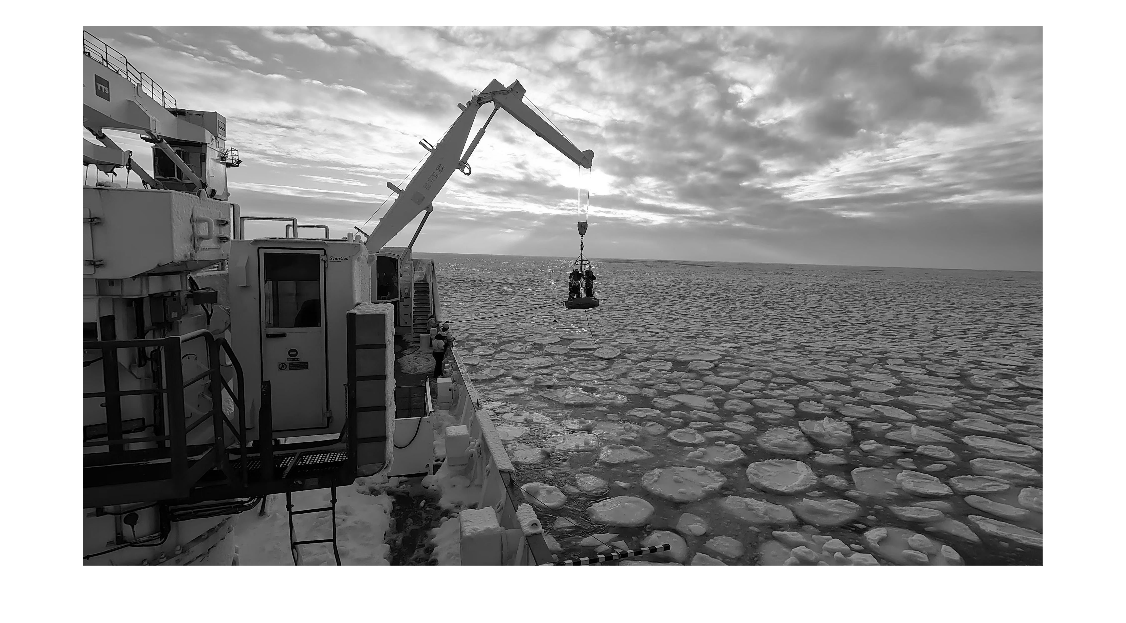

%% Detect pancake ice floes from an image

% Step 1: Read the image and convert to grayscale.
I1 = im2gray(imread("C:\Users\regin\Documents\MATLAB\Winter cruise seg\frame_0004.jpg"));

% Display the original grayscale image
imshow(I1)

xlim([1 3841])
ylim([1 2161])

%title('Original Image');

%% Step 2: Create a binary image using adaptive thresholding.
% Adaptive thresholding automatically adjusts the threshold value for different regions of the image.
bw = imbinarize(I1, "adaptive", "ForegroundPolarity", "bright");

% Display the binary image
imshow(bw)
%title('Binary Image after Adaptive Thresholding');

%% Step 3: Remove small objects from the binary image.
% This removes all connected components (objects) that have fewer than 500 pixels.
bw = bwareaopen(bw, 500);

% Display the cleaned binary image
imshow(bw)
%title('Binary Image after Removing Small Objects');

%% Step 4: Perform morphological closing.
% Create a disk-shaped structuring element with a radius of 2.
se = strel('disk', 2);

% Morphological closing is a dilation followed by an erosion, which closes small gaps in the objects.
bw = imclose(bw, se);

% Display the image after morphological closing
imshow(bw)
%title('Binary Image after Morphological Closing');

%% Step 5: Fill holes in the binary image.
% This operation fills in any background pixels that are surrounded by foreground pixels (holes).
bw = imfill(bw, 'holes');

% Display the image after filling holes
imshow(bw)
%title('Binary Image after Filling Holes');

%% Step 6: Trace the exterior boundaries of objects.
% Find boundaries of the objects in the binary image.
[B, L] = bwboundaries(bw, 'noholes');

% Display the labeled image with different colors for different objects
imshow(label2rgb(L, @jet, [.5 .5 .5]))
%title('Detected Boundaries')
hold on

% Plot the boundaries on the image
for k = 1:length(B)
  boundary = B{k};
  plot(boundary(:,2), boundary(:,1), 'w', 'LineWidth', 2)
end

%% Step 7: Analyze the roundness of detected pancakes and display values larger than the threshold.

% Measure area and centroid for each labeled region.
stats = regionprops(L, 'Area', 'Centroid');

% Define roundness threshold for identifying pancake ice floes.
threshold = 0.4;

% Loop over the boundaries to calculate roundness and display results.
for k = 1:length(B)
  % Obtain (X,Y) boundary coordinates for label 'k'
  boundary = B{k};

  % Compute an estimate of the object's perimeter
  delta_sq = diff(boundary).^2;    
  perimeter = sum(sqrt(sum(delta_sq, 2)));
  
  % Obtain the area for label 'k'
  area = stats(k).Area;
  
  % Compute the roundness metric
  metric = 4 * pi * area / perimeter^2;
  
  % Display the roundness metric
  metric_string = sprintf('%2.2f', metric);

  % Mark objects with roundness above the threshold
  if metric > threshold
    centroid = stats(k).Centroid;
    plot(centroid(1), centroid(2), 'ko');
  end

  % Label objects with roundness significantly higher than the threshold
  if metric > 0.45
    text(boundary(1, 2) - 35, boundary(1, 1) + 13, metric_string, 'Color', 'blue', 'FontSize', 14, 'FontWeight', 'bold')
  end
end
